# SOOT Sparse blind deconvolution Matlab toolbox

## Implements the regularized $\ell_1/\ell_2$ norm ratio restoration from

Euclid in a Taxicab: Sparse Blind Deconvolution with Smoothed $\ell_1/\ell_2$ Regularization IEEE Signal Processing Letters, May 2015 [http://dx.doi.org/10.1109/LSP.2014.2362861](http://dx.doi.org/10.1109/LSP.2014.2362861)

% History
% 2015/04/11: version 1.0

clc; close all; clear all

## load xtrue (sparse signal) and htrue (blur kernel)

try
  load('true_data.mat') ; % from .mat file if compatible
catch
  htrue = csvread('htrue.csv'); % from .csv file
  xtrue = csvread('xtrue.csv'); % from .csv file
end

## initialization

[x0,h0,epsx,hmin,hmax,epsh] = initialization(xtrue,htrue) ;

## observation

Choose the standard deviation of the gaussian noise

noise_Std = 0.01 ;
% noise_Std = 0.02 ;
% noise_Std = 0.03 ;

% Change to choose another realization of gaussian noise
seed = 1 ;
[y,alpha,beta,eta,lambda,NbIt,NbItx,NbIth] = observation(xtrue,htrue, noise_Std, seed) ;
% Note that parameter beta must satisfy beta < eta^2/alpha

## SOOT algorithm

[xS, hS,TimeS,norm1_xS,norm2_xS,norm1_hS,norm2_hS ] = ...
  SOOTalgorithm(x0, h0, xtrue, htrue, y, alpha,beta,eta, ...
  lambda, epsx, hmin, hmax, epsh, NbIt, NbItx, NbIth ) ;

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
INITIALIZATION:
----------------------------
alpha = 7.8146e-07, beta = 1e-07, eta = 0.041512
regularization parmaeter = 0.093187
----------------------------
Crit = 3.4063
----------------------------
x : l1  = 0.034942, l2  = 0.058071
h : l1  = 0.16335, l2  = 0.20576
~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
 
----------------------------------
Iteration = 134
Crit = 0.1239
Time = 13.2682
----------------------------
x : l1  = 0.0033566 l2  = 0.0099549
----------------------------
h : l1  = 0.012238 l2  = 0.016477
----------------------------------


## Display result

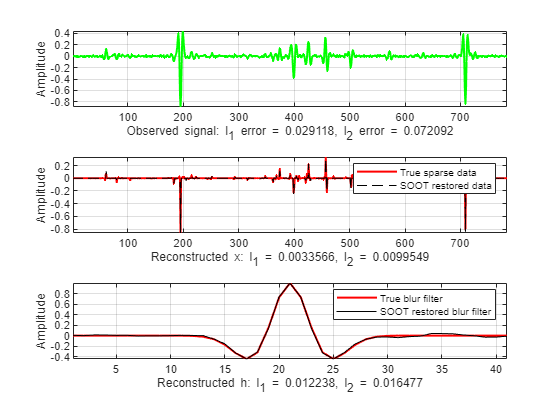

norml1_y = sum(abs(y-xtrue)) / length(xtrue) ;
norml2_y = sqrt( (sum((y-xtrue).^2)) / length(xtrue)) ;

figure
clf
title('SOOT l_1/l_2 sparse blind deconvolution')
subplot 311
plot(y,'g','linewidth',1.5) ;
xlabel(['Observed signal: l_1 error = ',num2str(norml1_y),', l_2 error = ',num2str(norml2_y)])
ylabel('Amplitude')
axis tight;grid on
subplot 312
plot(xtrue,'r','linewidth',1.5) ; hold on
plot(xS,'k--')
xlabel(['Reconstructed x: l_1 = ',num2str(norm1_xS(end)),', l_2 = ',num2str(norm2_xS(end))])
ylabel('Amplitude')
axis tight;grid on
legend('True sparse data','SOOT restored data')
subplot 313
plot(htrue,'r','linewidth',1.5) ; hold on
plot(hS,'k')
xlabel(['Reconstructed h: l_1 = ',num2str(norm1_hS(end)),', l_2 = ',num2str(norm2_hS(end))])
ylabel('Amplitude')
axis tight;grid on
legend('True blur filter','SOOT restored blur filter')